# Summations

clear; clc;
X = [-1, 1];  % BPSK constellation points (BPSK symbols are -1 and 1)
Q = 0.5;  % Probability for each symbol in BPSK (equally likely)

N = 2;  % Number of quadrature points
nodes = [-0.707107, 0.707107];  % Quadrature nodes (z1, z2)
weights = [0.886227, 0.886227];  % Quadrature weights (w1, w2)

SNR = 1; 

G = @(z) (1/pi) * exp(-abs(z).^2);

% Rho values to evaluate, ranging from 0 to 1
rho_values = linspace(0, 1, 1000);

% Initialize E0(rho) values
Eo_rho = zeros(size(rho_values));

% Start the timer
tic;

% Loop over rho values to calculate E0(rho)
for i = 1:length(rho_values)
    rho = rho_values(i);  % Set current rho value
    integral_sum = 0;  % Initialize integral sum for the current rho
    
    % Loop over BPSK symbols (x = -1 and x = 1)
    for x = X
        quadrature_sum = 0;  % Initialize quadrature sum for the current symbol
        
        % Nested loop over quadrature nodes
        for j = 1:N
            for k = 1:N
                z = nodes(j) + 1i * nodes(k);  % Combine nodes into complex value z
                fp_sum = 0;
                for x_bar = X
                    fp_sum = fp_sum + (Q * (G(z + sqrt(SNR)*x - sqrt(SNR)*x_bar).^(1/(1 + rho))));
                end
                fp = fp_sum / G(z).^(1/(1 + rho));
                quadrature_sum = quadrature_sum + weights(j) * weights(k) * fp.^rho;
            end
        end
        % Accumulate the integral sum for the current symbol
        integral_sum = integral_sum + Q * quadrature_sum;
    end
    
    % Calculate E0(rho) for the current rho value
    Eo_rho(i) = -log2((1/pi) * integral_sum);
end

elapsed_time = toc;
disp(['Elapsed time for computation: ', num2str(elapsed_time), 's']);

Elapsed time for computation: 0.028145s


disp(['Elapsed time for computation: ', num2str(elapsed_time * 1000), 'ms']);

Elapsed time for computation: 28.1451ms


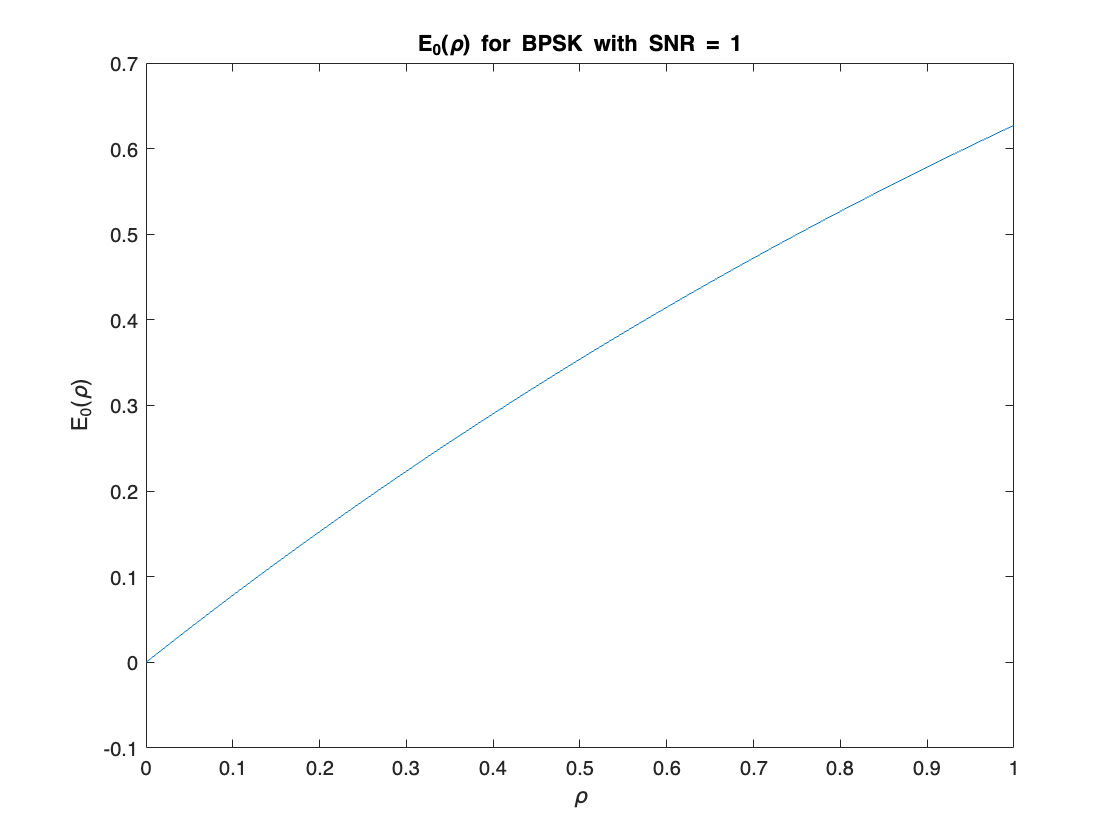

figure;
plot(rho_values, Eo_rho);
xlabel('\rho'); 
ylabel('E_0(\rho)');
title(['E_0(\rho) for BPSK with SNR = ', num2str(SNR)]);

disp(Eo_rho);

   -0.0000    0.0008    0.0016    0.0024    0.0032    0.0040    0.0048    0.0056    0.0064    0.0072    0.0080    0.0088    0.0096    0.0104    0.0112    0.0120    0.0128    0.0136    0.0144    0.0152    0.0160    0.0168    0.0176    0.0184    0.0192    0.0200    0.0208    0.0216    0.0224    0.0232    0.0240    0.0248    0.0255    0.0263    0.0271    0.0279    0.0287    0.0295    0.0303    0.0311    0.0319    0.0327    0.0334    0.0342    0.0350    0.0358    0.0366    0.0374    0.0382    0.0389    0.0397    0.0405    0.0413    0.0421    0.0429    0.0436    0.0444    0.0452    0.0460    0.0468    0.0475    0.0483    0.0491    0.0499    0.0507    0.0514    0.0522    0.0530    0.0538    0.0545    0.0553    0.0561    0.0569    0.0576    0.0584    0.0592    0.0600    0.0607    0.0615    0.0623    0.0631    0.0638    0.0646    0.0654    0.0661    0.0669    0.0677    0.0685    0.0692    0.0700    0.0708    0.0715    0.0723    0.0731    0.0738    0.0746    0.0754    0.0761    0.0769    0.0776